# Reproducing FIgure 1 from E.J. OBrien et al. - A Simple Extreme Value Problem

% Initial commands
clear, clc, close all

RunSim = true;

% First step - set up full script to do calculations and graphs for a
% single case. Use functions so that it is clean and concise.

% Next step - use the same functions, without comments and plots, in loops
% to perform 20 simulations for each number of workdays (3).

% Create a normal distribution according to the example, ParentDist
ParentDist = makedist('Normal','mu',40,'sigma',5);
% The number of observations per day
NumObpDay = 3000;

% The total number of workdays (for 3 samples)
NumWorkDays = [200 500 1000];

% Get all data, NumObpDay x NumWD
D = random(ParentDist,NumObpDay,NumWorkDays(3));

% xMaxes is good for tails and CDFs
xMaxes = 50:0.1:75;
% xParent is for the full Overview
% Get data for plot
xParent = 10:0.1:75;
yPDFParent = pdf(ParentDist,xParent);

% Plot the original data in histogram form along with matching normal curve
fOverview = figure('Name','Overview');
plot(xParent,yPDFParent)
title('Overview')
xlabel('X - Load Effect'); ylabel('PDF')
set(gca,'YTick', [])
hold on
histogram(D,'EdgeAlpha',0.1,'FaceColor','none','normalization','pdf')
% Reset x axis limits
xlim([40 70])

First we plot the original distribution of the load effect. In this case it is a perfect normal distribution (hence the blue fit).

For this exercise, we have **1000 days** worth of observations, with **3000 observations per day**.

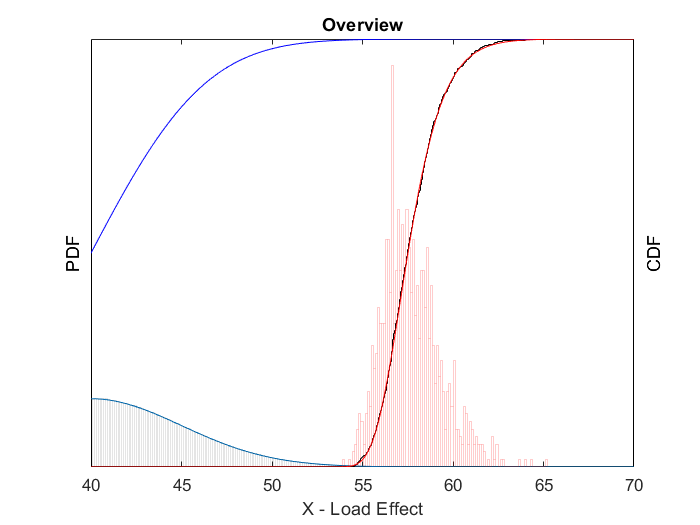


% Compute daily maximum data
DMax = max(D)';

% Plot Histogram of Maxes on the same plot
histogram(DMax,100,'EdgeColor','r','EdgeAlpha',0.2,'FaceColor','none','normalization','pdf')

% Emperical cdf (Ecdf) is a function that ranks data points in a sample (DMaxR) and gives
% the probability of non-exceedance (DMaxCDF)... it plots when given no variable 
[DMaxECDF, DMaxRank] = ecdf(DMax); DMaxRank = DMaxRank';
% Plot the CDF on the same plot, but with a new y-axis
yyaxis right
% Use stairs to introduce stepped shape which is mathematically correct
stairs(DMaxRank,DMaxECDF,'k')
ylabel('CDF')
set(gca,'YTick',[],'YColor','k')
% We can also plot the CDF of the parent distribution and the distribution
% of maximums. We know the exact dist of maximums by raising to the power

% Plot the exact CDF of both the original data, and the maximums
DCDF = cdf(ParentDist,xParent);
DMaxCDF = DCDF.^NumObpDay;

figure(fOverview)
yyaxis right
plot(xParent,DCDF,'b-')
% DMaxCDF is the exact distribution... see p 188 of Ang and Tang
plot(xParent,DMaxCDF,'r-')

Next we take the maximum from each day. We now have a sample of 1000 maximums (red).

We plot a histogram of these maximums, along with the emperical CDF on a new axis.

*Now the trick is that we want to do a least squares fit for only the top 30% of values from the 1000 daily maximum LEs. *

*We do NOT take the top 30% and treat them as a new sample...instead we must be careful to fit just the tail.*

*We use probability paper plots to illustrate this for the Normal case... but then use fminsearch with LeastMeanSquaresFit*

At this point we have 2 samples.

- D, the Parent sample of all values

- DMax, the sample of daily maximums

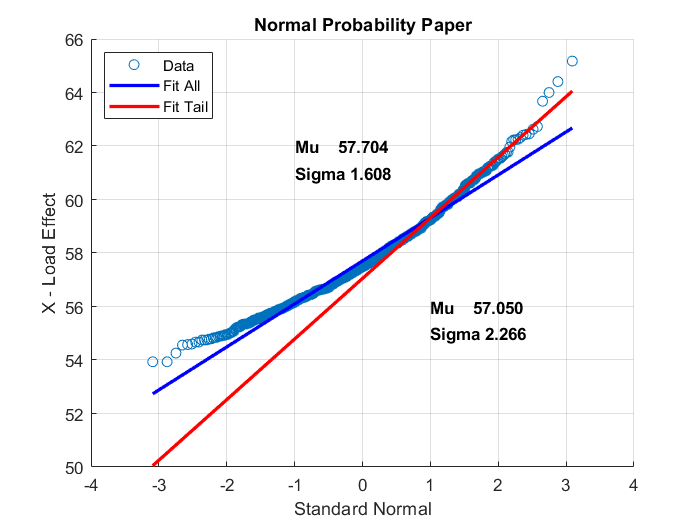


% Calculate cut-off index, COi and cut-off value, COv
TailP = 0.30;
COi = round(length(DMax)*(1-TailP));
COv = DMaxRank(COi);

% We add a third, which is all values above a certain threshold
% That threshold will be the lowest value in the top 30% of DMax values
% Collect all values above the cut-off value
DMaxCO = DMax(DMax > COv);
DMaxRankCO = DMaxRank(DMax > COv);
DCO = D(D > COv);

% At this point we have 4 samples.
%   D, the Parent sample of all values
%   DMax, the sample of daily maximums
%   DMaxCO, DMax > the Threshold (Cutoff)
%   DCO, D > the Threshold (Cutoff)


% For Normal we use probability paper plots (easily linearized)
% Normal probability paper plot
% Create Vector of Indices
i = 1:length(DMaxRank);
% Create Vector of Probabilities
PrI = i/(i(end)+1);

% It is also possible to use qqplot for this paper plotting...
% figure
% h = qqplot(DMax);
% xh = h(1).XData;
% yh = h(1).YData;
% figure
% h2 = qqplot(DMax,makedist('GeneralizedExtremeValue'));
                
% Get the Standard Normal Values for these Probabilities
NIPrI = norminv(PrI);
% Plot the Standard Normal Values to the Actual Maxes
figure
scatter(NIPrI,DMaxRank,'DisplayName','Data');

% Fit data to line; Coeff(1) = Sigma, Coeff(2) = Mu... NOT CORRECT
Coeff = polyfit(NIPrI, DMaxRank, 1);
% Plot the line and label it
xFit = linspace(min(NIPrI), max(NIPrI), 1000);
yFit = polyval(Coeff , xFit);
hold on;
plot(xFit, yFit, 'b-', 'LineWidth', 2,'DisplayName','Fit All');
grid on;
xlabel('Standard Normal'); ylabel('X - Load Effect')
text(-1,62,sprintf('Mu    %.3f',Coeff(2)),'FontSize',10,'FontWeight','bold','Color','k')
text(-1,61,sprintf('Sigma %.3f',Coeff(1)),'FontSize',10,'FontWeight','bold','Color','k')

% Fit top 30% of data to line; Coeff(1) = Sigma, Coeff(2) = Mu... CORRECT
Coeff = polyfit(NIPrI(COi:end), DMaxRank(COi:end), 1);
xFit = linspace(min(NIPrI), max(NIPrI), 1000);
yFit = polyval(Coeff , xFit);
hold on;
plot(xFit, yFit, 'r-', 'LineWidth', 2,'DisplayName','Fit Tail');
title('Normal Probability Paper')
legend('location','northwest')
text(1,56,sprintf('Mu    %.3f',Coeff(2)),'FontSize',10,'FontWeight','bold','Color','k')
text(1,55,sprintf('Sigma %.3f',Coeff(1)),'FontSize',10,'FontWeight','bold','Color','k')

Note that the red curve is the correct one, fitting only the tail.

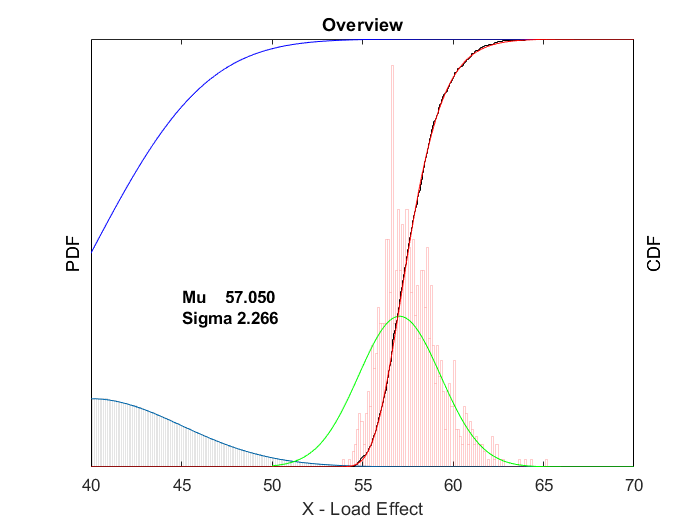

% Create a distribution out of the second fit (top 30%) and plot normal curve
% on original figure
NORMxpd = makedist('normal','mu', Coeff(2),'sigma',Coeff(1));
NORMxpdf = pdf(NORMxpd,xMaxes);
NORMxcdf = cdf(NORMxpd,xMaxes);
figure(fOverview)
hold on
yyaxis left
plot(xMaxes,NORMxpdf,'g-')
text(45,0.200,sprintf('Mu    %.3f',NORMxpd.mu),'FontSize',10,'FontWeight','bold','Color','k')
text(45,0.175,sprintf('Sigma %.3f',NORMxpd.sigma),'FontSize',10,'FontWeight','bold','Color','k')

We plot this tail-fit distribution on the original plot to show the tail modelling.

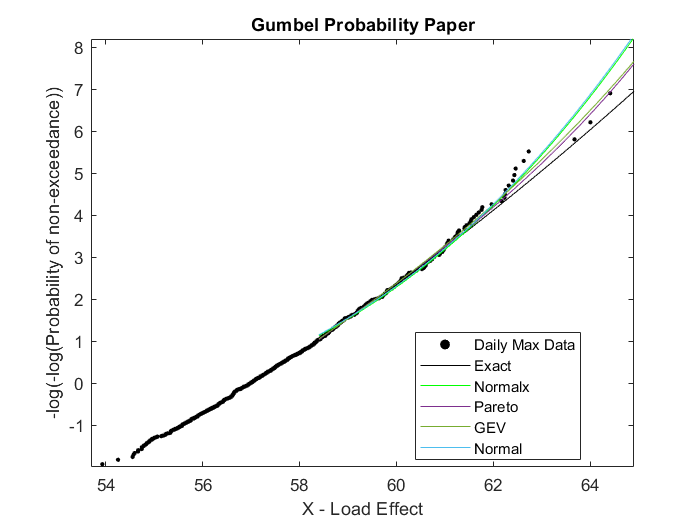

% The paper by EJOBrien uses Gumbel probability paper
% The Gumbel probability paper involves taking the -log(-log(CDF))
% Plot the original data (scatter)
fGumbelPP = figure('Name','Probability Paper');
scatter(DMaxRank,-log(-log(DMaxECDF)),7,'k','filled','DisplayName','Daily Max Data');
xlabel('X - Load Effect'); ylabel('-log(-log(Probability of non-exceedance))')
title('Gumbel Probability Paper')
legend('location','best')
xlim([53.7 64.9]); ylim([-2 8.2])
box on
xticks(54:2:64); yticks(-1:8)
hold on
% Add Exact CDF
plot(xParent(xParent> COv & xParent < max(DMax)),-log(-log(DMaxCDF(xParent > COv & xParent < max(DMax)))),'k-','DisplayName','Exact')
% Add Normal CDF fit
NormalxLine = plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(NORMxcdf(xMaxes > COv & xMaxes < max(DMax)))),'g-','DisplayName','Normalx');

% Paretotails... still have to figure this one out
PTfit = paretotails(DMax,0.1,(1-TailP));
PTcdf = cdf(PTfit,xMaxes);
ParetoLine = plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(PTcdf(xMaxes > COv & xMaxes < max(DMax)))),'DisplayName','Pareto');


% LeastMeanSquaresFit is a function which takes in 1) Data set of Maxes
% and 2) Fit Type (GEV, Rice, Weibull, Normal) and 3) Top Tail %
% And gives out A (parameters of dist)

FitType = 'GeneralizedExtremeValue';
GEVp = LeastMeanSquaresFit(DMax,FitType,TailP);
GEVcdf = cdf(FitType,xMaxes,GEVp(1),GEVp(2),GEVp(3));

FitType = 'Weibull';
WEIp= LeastMeanSquaresFit(DMax,FitType,TailP);
WEIcdf = cdf(FitType,xMaxes,WEIp(1),WEIp(2));

FitType = 'Normal';
NORMp = LeastMeanSquaresFit(DMax,FitType,TailP);
NORMcdf = cdf(FitType,xMaxes,NORMp(1),NORMp(2));

figure(fGumbelPP)
GEVLine = plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(GEVcdf(xMaxes > COv & xMaxes < max(DMax)))),'DisplayName','GEV');
NormalLine = plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(NORMcdf(xMaxes > COv & xMaxes < max(DMax)))),'DisplayName','Normal');

%WeibullLine = plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(WEIcdf(xMaxes > COv & xMaxes < max(DMax)))),'DisplayName','Weibull');

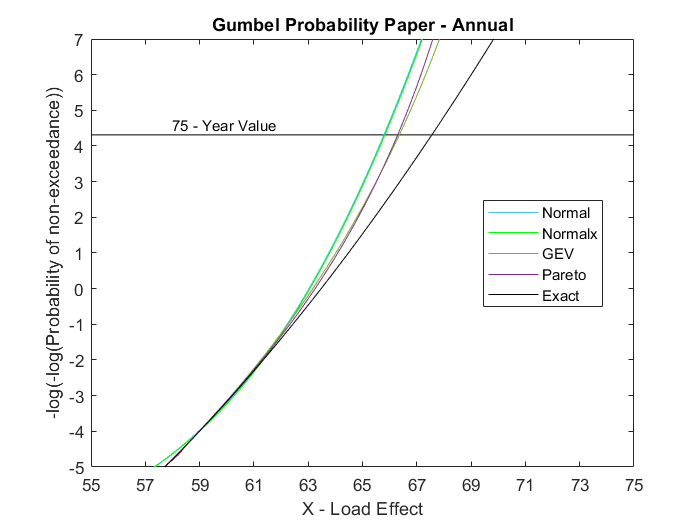


% Convert to annual by raising to the power of 250
AnnualProbPaper = figure('Name','Annual Max CDFs');
% Calculate 75-year return period and plo
SF = 1-(1/75);
plot([55 75],[-log(-log(SF)) -log(-log(SF))],'k-','HandleVisibility',"off")
hold on
% Label particulars
xlabel('X - Load Effect'); ylabel('-log(-log(Probability of non-exceedance))')
title('Gumbel Probability Paper - Annual')
text(58,4.6,'75 - Year Value','FontSize',9,'Color','k')
legend('location','best')
xlim([55 75]); ylim([-5 7])
box on
xticks(55:2:75); yticks(-5:7)

% Convert to annual by raising to the power of 250
DMaxCDFa = DMaxCDF.^250;
NORMcdfa = NORMcdf.^250;
NORMxcdfa = NORMxcdf.^250;
GEVcdfa = GEVcdf.^250;
WEIcdfa = WEIcdf.^250;
PTcdfa = PTcdf.^250;

% plot annual CDFs from different distributions
plot(xMaxes,-log(-log(NORMcdfa)),'Color',NormalLine.Color,'DisplayName','Normal')
plot(xMaxes,-log(-log(NORMxcdfa)),'Color',NormalxLine.Color,'DisplayName','Normalx')
plot(xMaxes,-log(-log(GEVcdfa)),'Color',GEVLine.Color,'DisplayName','GEV')
%plot(xMaxes,-log(-log(WEIcdfa)),'Color',WeibullLine.Color,'DisplayName','Weibull')
plot(xMaxes,-log(-log(PTcdfa)),'Color',ParetoLine.Color,'DisplayName','Pareto')
% Plot Exact Distribution
plot(xParent,-log(-log(DMaxCDFa)),'k-','DisplayName','Exact')


% Calculate Exact75 Year Characteristic Value
[~,closestIndex] = min(abs(SF-DMaxCDFa));
Exact75 = xParent(closestIndex);
% Calculate 75 Year Characteristic Value for the others
[~,closestIndex] = min(abs(SF-GEVcdfa));
GEV75 = xMaxes(closestIndex);
[~,closestIndex] = min(abs(SF-NORMcdfa));
NORM75 = xMaxes(closestIndex);

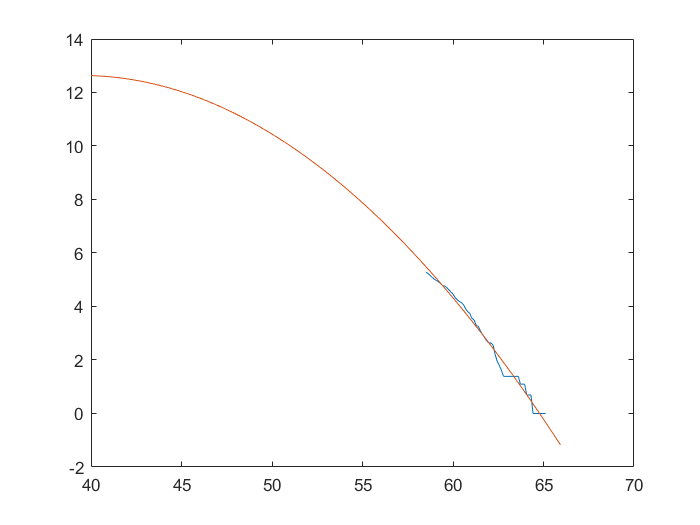

% RICE Distribution Estimation

% Calculate Rice Distribution through Fitting of Normalized Upcrossing Histogram
% The details of the normalized histogram (bin size and starting bin) are
% important variables for optimization
Division = 0.1163;
xUC = 40:Division:66;

% Rather than using a Division... lets let the eCDF decide! What are the
% x-values of the eCDF? First, let's create the eCDF for the full data set

% Emperical cdf (Ecdf) is a function that ranks data points in a sample (DMaxR) and gives
% the probability of non-exceedance (DMaxCDF)... it plots when given no variable 
[DECDF, DRank] = ecdf(D(:)); DRank = DRank';
DECDFco = DECDF(DRank > COv);
DRankco = DRank(DRank > COv);

% Start with DMax
UC = UpCross(DMax,xUC);
% Normalization... everything after v0 (threshold) has to add to 1
NormalizeSum = sum(UC(xUC > COv)*Division);
DMaxRiceFit = figure;
bar(xUC,UC./NormalizeSum,1,'FaceColor',[.8 .8 .8],'EdgeColor',[0 0 0],'LineWidth',1)
xlabel('X - Load Effect'); ylabel('Normalized Upcrossings')
title('DMax Normalized Upcrossing')
xlim([57 66])

% Get ln of top 30 percent values
UC30 = UC(xUC > COv);
LnUC = log(UC30);
% Get x indices for top 30 percent values
xUC30 = xUC(xUC > COv);

% Plot best fit parabola to verify concavity (we want negative)
figure()
xlabel('X - Load Effect');
title('DMax Line of Best Fit')
plot(xUC30,LnUC)
p = polyfit(xUC30(LnUC > -100),LnUC(LnUC > -100),2);
% Solve for 3 variables, Sigma, M, and SigmaP
Sigma = sqrt(-1/(2*p(1)));
M = p(2)*Sigma^2;
SigmaP = 2*pi*Sigma*exp((p(3)+M^2/(2*Sigma^2)));
hold on
y = p(1)*xUC.^2+p(2)*xUC+p(3);
plot(xUC,y)

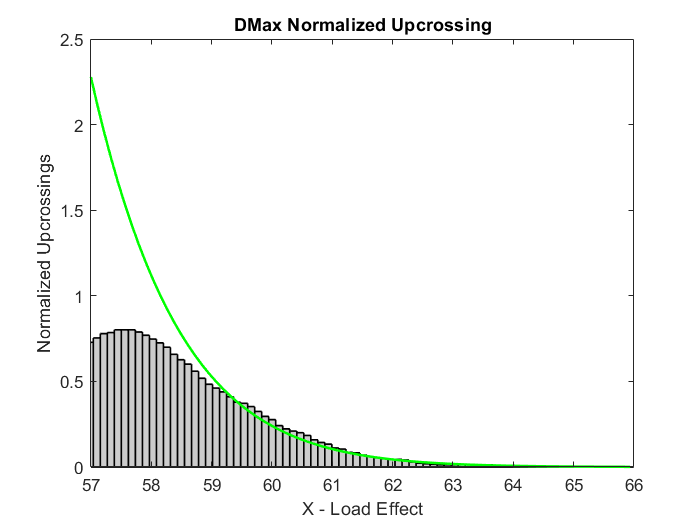


% Take new parameters and plot on histogram (both Y and v)
Y = exp(y);
figure(DMaxRiceFit)
hold on
plot(xUC,Y./NormalizeSum,'r-','LineWidth',1.5)
v = (SigmaP/(2*pi*Sigma))*exp(-(((xUC-M).^2)/(2*Sigma^2)));
plot(xUC,v./NormalizeSum,'g-','LineWidth',1.5)

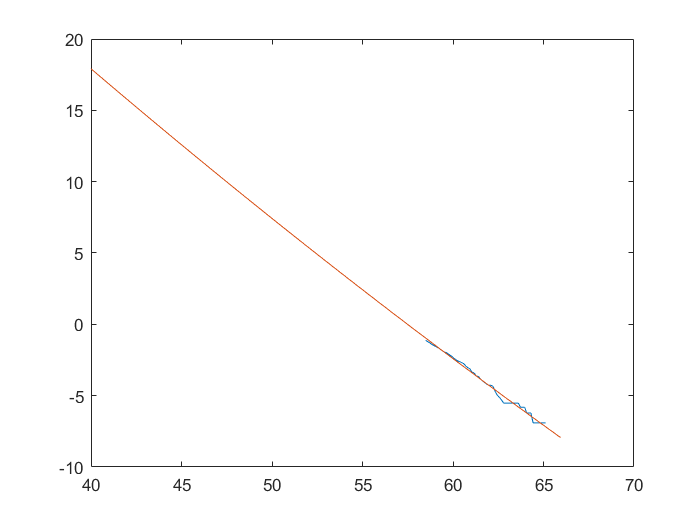

% Now do the same for full dataset, D
UC = UpCross(D,xUC);
% Take the mean of each day
UCMean = mean(UC,2);
DRiceFit = figure;
NormalizeSum = sum(UCMean(xUC > 57)*Division);
bar(xUC,UCMean./NormalizeSum,1,'FaceColor',[.8 .8 .8],'EdgeColor',[0 0 0],'LineWidth',1)
xlabel('X - Load Effect'); ylabel('Normalized Upcrossings')
title('D Means Normalized Upcrossing')
xlim([57 66])

% Get ln of values

UCaM_ = UCMean(xUC > COv);
xUC30 = xUC(xUC > COv);
LnUC = log(UCaM_);

figure()
xlabel('X - Load Effect');
title('D Means Line of Best Fit')
plot(xUC30,LnUC)
p = polyfit(xUC30(LnUC > -100),LnUC(LnUC > -100),2);
sigma = sqrt(-1/(2*p(1)));
m = p(2)*sigma^2;
sigmaprime = 2*pi*sigma*exp((p(3)+m^2/(2*sigma^2)));
hold on
y = p(1)*xUC.^2+p(2)*xUC+p(3);
plot(xUC,y)

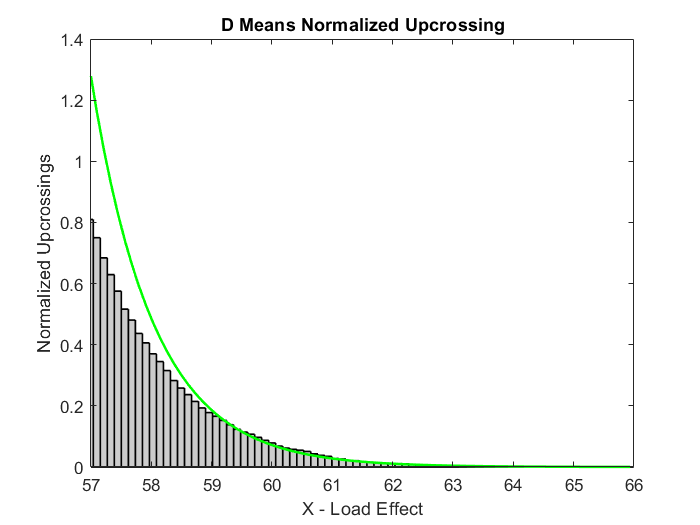


Y = exp(y);
figure(DRiceFit)
hold on
plot(xUC,Y./NormalizeSum,'r-','LineWidth',1.5)

v = (sigmaprime/(2*pi*sigma))*exp(-(((xUC-m).^2)/(2*sigma^2)));
figure(DRiceFit)
hold on
plot(xUC,v./NormalizeSum,'g-','LineWidth',1.5)


sum(v./NormalizeSum)

ans = 4.0683e+08

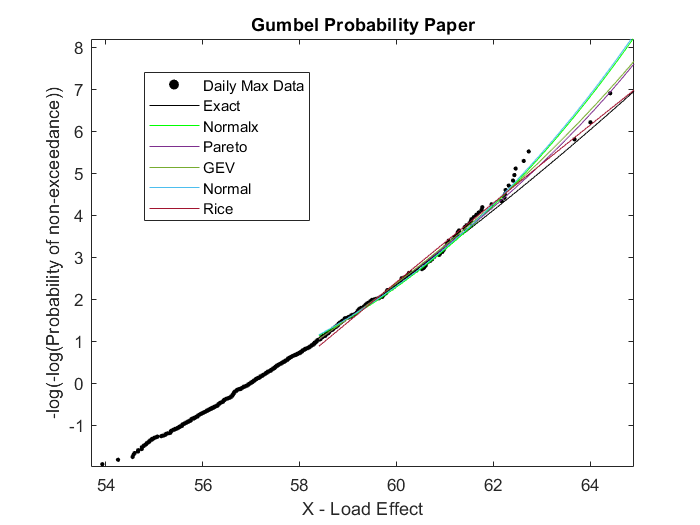

v = v./NormalizeSum;

% CDF of Rice
R = 1;
%RICEcdf = exp(-R*(SigmaP/(2*pi*Sigma))*exp(-0.5.*((xMaxes-M)./Sigma).^2));
RICEcdf = exp(-R*(sigmaprime/(2*pi*sigma))*exp(-0.5.*((xMaxes-m)./sigma).^2));
%RICEcdf = exp(-R*(SigmaP/(2*pi*Sigma))*exp(-0.5.*((xUC-M)./Sigma)));

figure(fGumbelPP)
plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(RICEcdf(xMaxes > COv & xMaxes < max(DMax)))),'DisplayName','Rice')

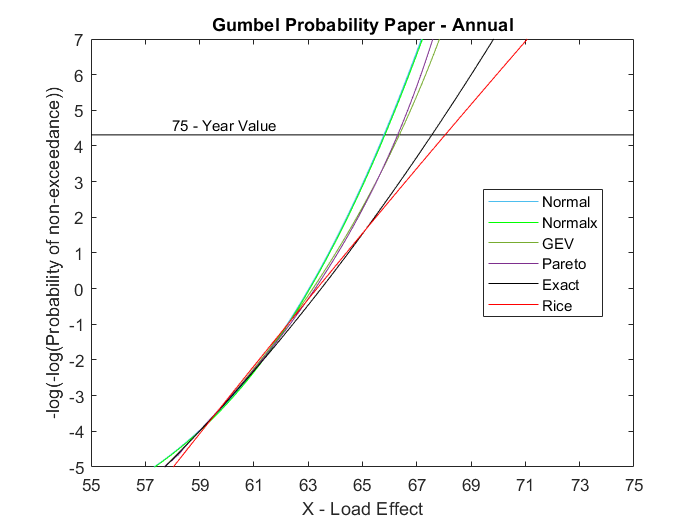

figure(AnnualProbPaper)
plot(xMaxes,-log(-log(RICEcdf.^250)),'r-','DisplayName','Rice')

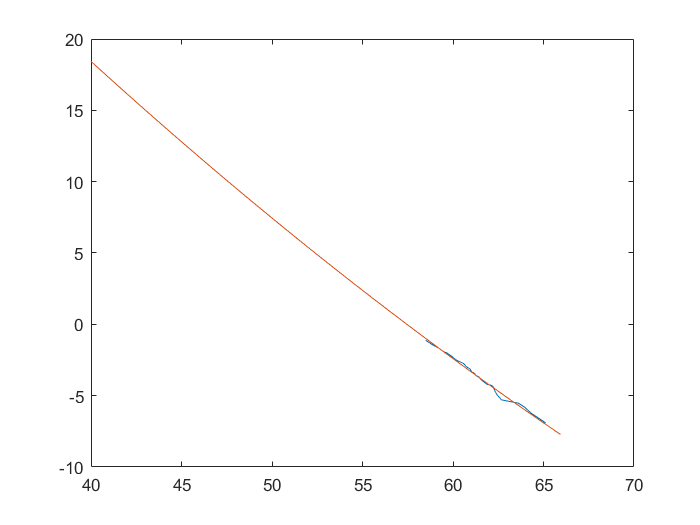


% Now do the same for full dataset, D ROUND 2

UC = UpCross(D,xUC);
%UC = UpCross(D(:),xUC);
%UCx = UpCrossx(D);
% Take the mean of each day
UCMean = mean(UC,2);
%UCMean = UC;
DRiceFit = figure;
% Normalize only above COv
NormThresh = 57;
NormalizeSum = sum(UCMean(xUC > NormThresh)*Division);
bar(xUC,UCMean./NormalizeSum,1,'FaceColor',[.8 .8 .8],'EdgeColor',[0 0 0],'LineWidth',1)
xlabel('X - Load Effect'); ylabel('Normalized Upcrossings')
title('D Means Normalized Upcrossing')
xlim([57 66])

% Get ln of values

UCaM_ = UCMean(xUC > COv);
D = diff(UCaM_);
UCaM_ = UCaM_(D~=0);
xUC30 = xUC(xUC > COv);
xUC30 = xUC30(D~=0);
LnUC = log(UCaM_);

figure()
xlabel('X - Load Effect');
title('D Means Line of Best Fit')
plot(xUC30,LnUC)
p = polyfit(xUC30(LnUC > -100),LnUC(LnUC > -100),2);
sigma = sqrt(-1/(2*p(1)));
m = p(2)*sigma^2;
sigmaprime = 2*pi*sigma*exp((p(3)+m^2/(2*sigma^2)));
hold on
y = p(1)*xUC.^2+p(2)*xUC+p(3);
plot(xUC,y)

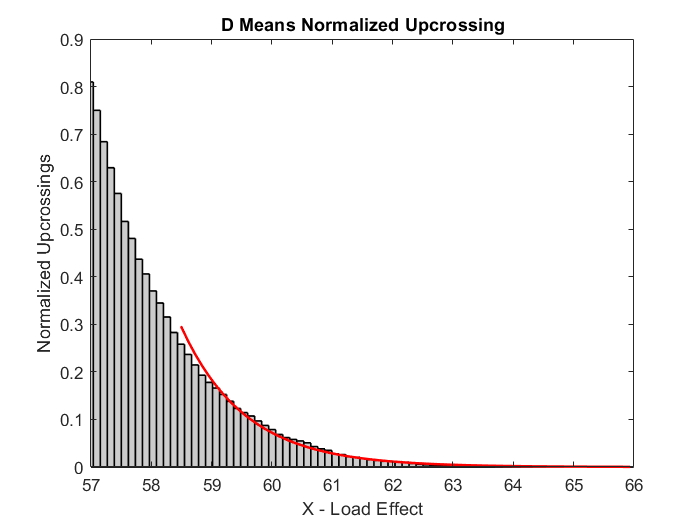


Y = exp(y);
figure(DRiceFit)
hold on
plot(xUC(xUC>COv),Y(xUC>COv)./NormalizeSum,'r-','LineWidth',1.5)

v = (sigmaprime/(2*pi*sigma))*exp(-(((xUC-m).^2)/(2*sigma^2)));
figure(DRiceFit)
hold on
plot(xUC(xUC>COv),v(xUC>COv)./NormalizeSum,'r-','LineWidth',1.5)

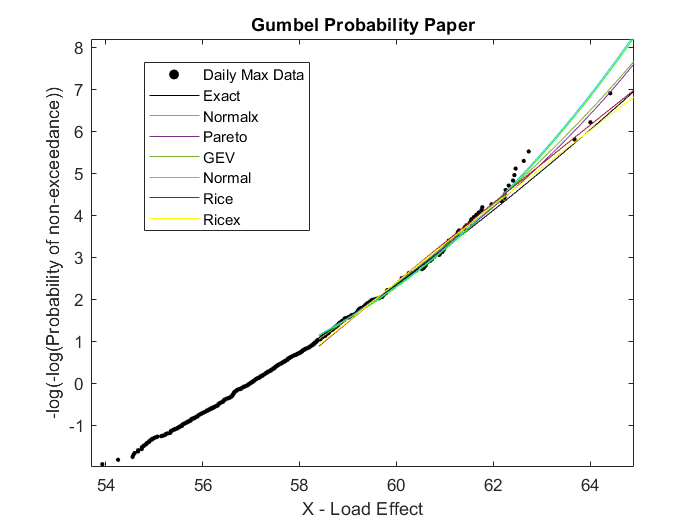



v = v./NormalizeSum;

% CDF of Rice
R = 1;
%RICEcdf = exp(-R*(SigmaP/(2*pi*Sigma))*exp(-0.5.*((xMaxes-M)./Sigma).^2));
RICEcdf = exp(-R*(sigmaprime/(2*pi*sigma))*exp(-0.5.*((xMaxes-m)./sigma).^2));
%RICEcdf = exp(-R*(SigmaP/(2*pi*Sigma))*exp(-0.5.*((xUC-M)./Sigma)));

figure(fGumbelPP)
plot(xMaxes(xMaxes > COv & xMaxes < max(DMax)),-log(-log(RICEcdf(xMaxes > COv & xMaxes < max(DMax)))),'y-','DisplayName','Ricex')

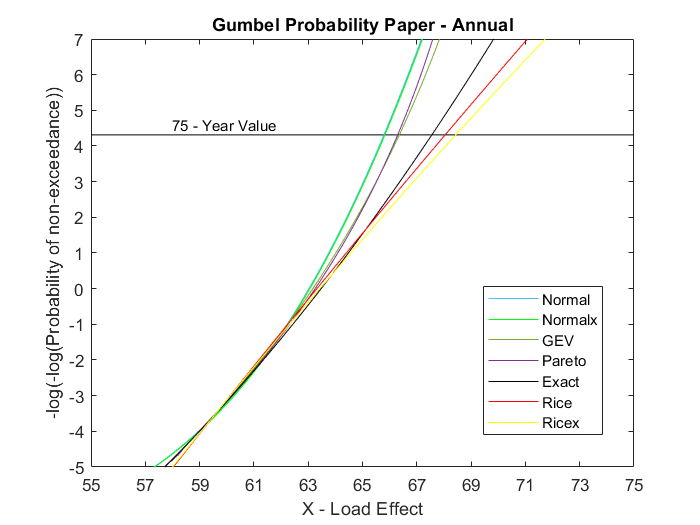

% CDF of Rice
R = 250;
%RICEcdf = exp(-R*(SigmaP/(2*pi*Sigma))*exp(-0.5.*((xMaxes-M)./Sigma).^2));
RICEacdf = exp(-R*(sigmaprime/(2*pi*sigma))*exp(-0.5.*((xMaxes-m)./sigma).^2));

figure(AnnualProbPaper)
plot(xMaxes,-log(-log(RICEacdf)),'y-','DisplayName','Ricex')

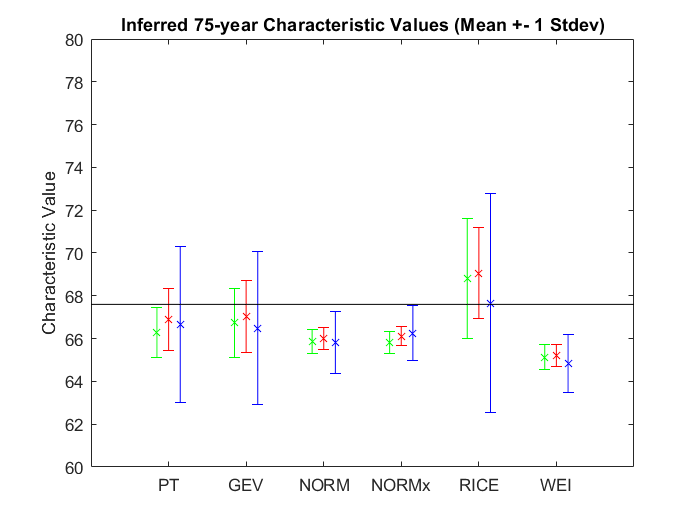








% Now we have to combine all that we've done into a quick format to put in
% a loop, to collect values for NumWorkDays = 200, 500, and 1000
% We will repeat this loop 20 times and examine the mean/stdev of each dist

if RunSim

[Results.PT, Results.GEV, Results.NORM, Results.NORMx, Results.RICE, Results.WEI] = deal(zeros(20,3));

for t = 1:20 % 20 sims
    for j = 1:3 % Each NumWorkDays
        % Get all data, NumObpDay x NumWD
        D = random(ParentDist,NumObpDay,NumWorkDays(j));
        % Compute daily maximum data
        DMax = max(D)';
        
        [DMaxECDF, DMaxRank] = ecdf(DMax); DMaxRank = DMaxRank';
        DCDF = cdf(ParentDist,xParent);
        DMaxCDF = DCDF.^NumObpDay;
        
        COi = round(length(DMax)*(1-TailP));
        COv = DMaxRank(COi);
        
        % Create Vector of Indices
        i = 1:length(DMaxRank);
        % Create Vector of Probabilities
        PrI = i/(i(end)+1);

        % Get the Standard Normal Values for these Probabilities
        NIPrI = norminv(PrI);
        
        % Fit top 30% of data to line; Coeff(1) = Sigma, Coeff(2) = Mu... CORRECT
        Coeff = polyfit(NIPrI(COi:end), DMaxRank(COi:end), 1);
        
        % Create a distribution out of the second fit (top 30%) and plot normal curve
        % on original figure
        NORMxpd = makedist('normal','mu', Coeff(2),'sigma',Coeff(1));
        NORMxpdf = pdf(NORMxpd,xMaxes);
        NORMxcdf = cdf(NORMxpd,xMaxes);
        
        % Paretotails... still have to figure this one out
        PTfit = paretotails(DMax,0,(1-TailP));
        PTcdf = cdf(PTfit,xMaxes);
        
        % LeastMeanSquaresFit is a function which takes in 1) Data set of Maxes
        % and 2) Fit Type (GEV, Rice, Weibull, Normal) and 3) Top Tail %
        % And gives out A (parameters of dist)
        
        FitType = 'GeneralizedExtremeValue';
        GEVp = LeastMeanSquaresFit(DMax,FitType,TailP);
        GEVcdf = cdf(FitType,xMaxes,GEVp(1),GEVp(2),GEVp(3));
        
        FitType = 'Weibull';
        WEIp= LeastMeanSquaresFit(DMax,FitType,TailP);
        WEIcdf = cdf(FitType,xMaxes,WEIp(1),WEIp(2));
        
        FitType = 'Normal';
        NORMp = LeastMeanSquaresFit(DMax,FitType,TailP);
        NORMcdf = cdf(FitType,xMaxes,NORMp(1),NORMp(2));
        
        % Convert to annual by raising to the power of 250
        DMaxCDFa = DMaxCDF.^250;
        NORMcdfa = NORMcdf.^250;
        NORMxcdfa = NORMxcdf.^250;
        GEVcdfa = GEVcdf.^250;
        WEIcdfa = WEIcdf.^250;
        PTcdfa = PTcdf.^250;
        
        % Now do the same for full dataset, D
        UC = UpCross(D,xUC);
        % Take the mean of each day
        UCMean = mean(UC,2);
        NormalizeSum = sum(UCMean(xUC > 57)*Division);
        
        % Get ln of values
%         UCaM_ = UCMean(xUC > COv);
%         xUC30 = xUC(xUC > COv);
%         LnUC = log(UCaM_);
%         
        % Get ln of values
        UCaM_ = UCMean(xUC > COv);
        D = diff(UCaM_);
        UCaM_ = UCaM_(D~=0);
        xUC30 = xUC(xUC > COv);
        xUC30 = xUC30(D~=0);
        LnUC = log(UCaM_);

        p = polyfit(xUC30(LnUC > -100),LnUC(LnUC > -100),2);
        sigma = sqrt(-1/(2*p(1)));
        m = p(2)*sigma^2;
        sigmaprime = 2*pi*sigma*exp((p(3)+m^2/(2*sigma^2)));
        
        v = (sigmaprime/(2*pi*sigma))*exp(-(((xUC-m).^2)/(2*sigma^2)));
        v = v./NormalizeSum;
        
        % CDF of Rice
        R = 1;
        RICEcdf = exp(-R*(sigmaprime/(2*pi*sigma))*exp(-0.5.*((xMaxes-m)./sigma).^2));
        R = 250;
        RICEcdfa = exp(-R*(sigmaprime/(2*pi*sigma))*exp(-0.5.*((xMaxes-m)./sigma).^2));
        
        %RICEcdfa = RICEcdf.^250;
        
        [~,closestIndex] = min(abs(SF-RICEcdfa));
        RICE75 = xMaxes(closestIndex);
        % Calculate 75 Year Characteristic Value for the others
        [~,closestIndex] = min(abs(SF-GEVcdfa));
        GEV75 = xMaxes(closestIndex);
        [~,closestIndex] = min(abs(SF-NORMcdfa));
        NORM75 = xMaxes(closestIndex);
        [~,closestIndex] = min(abs(SF-NORMxcdfa));
        NORMx75 = xMaxes(closestIndex);
        [~,closestIndex] = min(abs(SF-WEIcdfa));
        WEI75 = xMaxes(closestIndex);
        [~,closestIndex] = min(abs(SF-PTcdfa));
        PT75 = xMaxes(closestIndex);
        
        Results.GEV(t,j) = GEV75;
        Results.NORM(t,j) = NORM75;
        Results.NORMx(t,j) = NORMx75;
        Results.WEI(t,j) = WEI75;
        Results.RICE(t,j) = RICE75;
        Results.PT(t,j) = PT75;
        
    end
   
end

CharVals = figure('Name','75-Year Characteristic Values');
Offset = [0.15 0 -0.15];
JCol{1} = [0,0,1];
JCol{2} = [1,0,0];
JCol{3} = [0,1,0];
FNames = fieldnames(Results);
hold on

for f = 1:length(FNames)
    for j = 1:3
        plot([f+Offset(j) f+Offset(j)],[mean(Results.(FNames{f})(:,j))-std(Results.(FNames{f})(:,j)) mean(Results.(FNames{f})(:,j))+std(Results.(FNames{f})(:,j))],'_-','Color',JCol{j})
        plot(f+Offset(j),mean(Results.(FNames{f})(:,j)),'x','Color',JCol{j})
    end
end

xlim([0 length(FNames)+1]); ylim([60 80])
xticklabels([{''} FNames' {''}])
plot([0 length(FNames)+1],[Exact75 Exact75],'k-')
box on
ylabel('Characteristic Value')
title('Inferred 75-year Characteristic Values (Mean +- 1 Stdev)')
end



% plot(x(x > COv & x < max(DMax)),-log(-log(RICEcdf(x > COv & x < max(DMax)))),'DisplayName','Rice')

% 
% GEV75 = []; NORM75 = [];


% %for z = 3:3
%     z = 3;
%     %for q = 1:20
%         q = 1;

% z, 3, q, 20
% 
% if z > 1 && q > 1
%     
%     GEV_1000 = GEV75(41:60);
%     GEV_500 = GEV75(21:40);
%     GEV_200 = GEV75(1:20);
%     NORM_1000 = NORM75(41:60);
%     NORM_500 = NORM75(21:40);
%     NORM_200 = NORM75(1:20);
%     
% end



% % Peak Over Threshold
% DMaxPOT = D(D > COv);
% [DMaxPOTeCDF, DMaxPOTR] = ecdf(DMax); DMaxPOTR = DMaxPOTR';
% 
% % Do the same for Parento with POT data
% % Create function to solve for parameters of GEV distribution fit to tail
% fnPar = @(param) sum((gpcdf(DMaxPOTR(COi:end),param(1),param(2),param(3)) - DMaxeCDF(COi:end)').^2);
% % Use gevfit to generate an initial guess
% B = gevfit(DMax);
% % Solve for parameters using fminsearch
% A =  fminsearch(fnGEV,B);

% % Try to make the normalized upcrossing graph (Figure 2)
% x = 50:0.1:70;
% % Average number of times x is exceeded in each day in D
% %for i = 1:size(D,2)
%     for j = 1:length(x)
%         %Up(j) = sum(D(:,i) > x(j));
%         Up(j) = sum(sum(D > x(j)))/1000;
%     end   
% %end

% figure
% plot(x,Up)
% xlim([57 66])
% 
% figure
% histogram(Up(Up>57),100,'normalization','pdf')
% xlim([57 66])



% Legacy... try Matlab's built in Gumbel (extreme value) probability paper plot
% % A = probplot('extreme value',DMax);


% Legacy... used to display normal curve approximation of all maximums (no tail fit)
% % % Fit maximums to normal distribution
% % npd = fitdist(DMax,'normal');
% % x = 50:0.1:70;
% % y = pdf(npd,x);
% % hold on
% % yyaxis left
% % plot(x,y,'r-')
% % text(45,0.3,sprintf('Mu: %.3f',npd.mu),'FontSize',11,'FontWeight','bold','Color','k')
% % text(45,0.275,sprintf('Sigma: %.3f',npd.sigma),'FontSize',11,'FontWeight','bold','Color','k')

% % Legacy Weibull plot
% % % Note that a and b are swaped with Alpha and Beta!
% % figure('Name','Overview')
% % npdx = makedist('weibull','a', a,'b',b);
% % x = 50:0.1:70;
% % y = pdf(npdx,x);
% % Yx = cdf(npdx,x);
% % hold on
% % yyaxis left
% % plot(x,y,'g-')
% % text(62,0.200,sprintf('Scale   %.3f',npdx.a),'FontSize',10,'FontWeight','bold','Color','k')
% % text(62,0.175,sprintf('Shape %.3f',npdx.b),'FontSize',10,'FontWeight','bold','Color','k')

% % Weibull Probability Paper Plot
% x = log(-log(1-PrI));
% y = log(DMaxR);
% figure
% scatter(x,y);
% 
% Coeff = polyfit(x(COi:end), y(COi:end), 1);
% b = 1/Coeff(1);
% a = exp(Coeff(2));
% xFit = linspace(min(x), max(x), 1000);
% yFit = polyval(Coeff , xFit);
% hold on;
% plot(xFit, yFit, 'r-', 'LineWidth', 2);
% title('Weibull Probability Paper')
% text(0,3.90,sprintf('Scale  %.3f',a),'FontSize',10,'FontWeight','bold','Color','k')
% text(0,3.85,sprintf('Shape %.3f',b),'FontSize',10,'FontWeight','bold','Color','k')
% grid on;
% ylabel('X - Load Effect')
% xlabel('Standard Normal')

% % Get Weibull CDF
% % Note that a and b are swaped with Alpha and Beta!
% WEIpd = makedist('weibull','a', a,'b',b);
% x = 50:0.1:70;
% y = pdf(WEIpd,x);
% WEIcdf = cdf(WEIpd,x);

%% Plot Weibull
%plot(x(x > COv & x < max(DMax)),-log(-log(WEIcdf(x > COv & x < max(DMax)))),'DisplayName','Weibull')



% [~,closestIndex] = min(abs(SF-GEVcdfxA));
% GEV75 = [GEV75; x(closestIndex)];
% [minValue,closestIndex] = min(abs(SF-NORMcdfxA));
% NORM75 = [NORM75; x(closestIndex)];